%% ========================================================================
%  ITALIAN DEBT DYNAMICS: SNOWBALL EFFECT & SPREAD ANALYSIS
%  ========================================================================
%  This script estimates the relationship between 
 spreads and
%  the snowball effect on Italian public debt using OLS with HAC standard
%  errors (Newey-West). Models include:
%    1. Baseline specification
%    2. Post-2010 interaction (structural break)
%    3. Threshold model (nonlinear spread effect)
%    4. Combined threshold + post-2010 interaction
%
%  Author: [Your Name]
%  Last updated: 2025
%  ========================================================================

clear; clc; close all;

%% =======================  SETTINGS  ====================================
config = struct();
config.file       = 'CRA_data.xlsx';
config.sheet      = 'DataToUse';
config.yearRange  = [1990, 2025];      % Years to include
config.breakYear  = 2010;              % Structural break year

% AMECO series codes
config.codes = struct(...
    'snowball',   'ADGGI',    ...  % Snowball effect (% GDP)
    'spread',     'ITA-GER',  ...  % BTP-Bund spread
    'debt',       'UDGG',     ...  % Gross debt (% GDP)
    'realGDP',    'OVGD',     ...  % Real GDP (2020 levels)
    'deflator',   'PCPH',     ...  % Consumption deflator
    'primBal',    'UBLGAP'    ...  % Cyclically-adjusted primary balance
);

% Output files (set to '' to skip export)
config.outputs = struct(...
    'descriptive', 'descriptive_stats.xlsx', ...
    'baseline',    'baseline_hac.xlsx',      ...
    'interaction', 'post2010_hac.xlsx',      ...
    'threshold',   'threshold_hac.xlsx'      ...
);

% Display settings
config.verbose = true;

%% ==================  READ & PREPARE DATA  ==============================
fprintf('=== Loading and preparing data ===\n\n');

=== Loading and preparing data ===




try
    [data, years] = loadAndPrepareData(config);
catch ME
    error('Data loading failed: %s', ME.message);
end

fprintf('Sample: %d-%d (%d observations)\n\n', ...
    min(years), max(years), numel(years));

Sample: 1996-2019 (24 observations)




%% ===================== DESCRIPTIVE STATISTICS ==========================
fprintf('=== Descriptive Statistics ===\n\n');

=== Descriptive Statistics ===




descTable = computeDescriptiveStats(data);
disp(descTable);

              Snowball    Spread    Debt_GDP    PrimBal    Growth     Inflation
              ________    ______    ________    _______    _______    _________

    Mean       2.4407     1.2612     117.49      -2.786     0.5816       1.898 
    Std        2.1702     1.1115       11.3      1.6062     1.8938       1.094 
    Min       -0.0007     0.1775     103.46     -6.1396    -5.4511    -0.45634 
    Max        8.3687     3.9975      134.8     -0.2002     3.8087       3.843 
    Median     1.7308     1.1546     116.31     -3.0221     1.0552      2.0358 
    N              24         24         24          24         24          24 




if ~isempty(config.outputs.descriptive)
    writetable(descTable, config.outputs.descriptive, 'WriteRowNames', true);
    fprintf('Exported to: %s\n\n', config.outputs.descriptive);
end

Exported to: descriptive_stats.xlsx




%% ===================== HAC BANDWIDTH ===================================
% Newey-West optimal bandwidth (annual data plug-in rule)
nObs = numel(data.sb);
hacLags = max(1, floor(4 * (nObs/100)^(2/9)));
fprintf('HAC bandwidth (Newey-West): %d lags\n\n', hacLags);

HAC bandwidth (Newey-West): 2 lags




%% ===================== MODEL ESTIMATION ================================

% ---- Model 1: Baseline ----
fprintf('\n%s\n', repmat('=', 1, 60));

fprintf('MODEL 1: BASELINE SPECIFICATION\n');

MODEL 1: BASELINE SPECIFICATION


fprintf('%s\n', repmat('=', 1, 60));


X1 = [ones(nObs,1), data.spr, data.b_lag, data.pb, data.g, data.pie];
names1 = {'const', 'spread', 'debt_lag', 'prim_bal', 'growth', 'inflation'};

results1 = estimateOLS_HAC(data.sb, X1, names1, hacLags);
printResults(results1, 'Baseline');


--- Baseline ---

                   Coef       SE_OLS      t_OLS      p_OLS       SE_HAC      t_HAC      p_HAC  
                 ________    ________    _______    ________    ________    _______    ________

    const          16.242      9.0946     1.7859    0.090966      7.5742     2.1444    0.045898
    spread         1.1781     0.57136     2.0619    0.053955     0.45064     2.6143    0.017561
    debt_lag     -0.11481    0.073954    -1.5524     0.13798    0.060062    -1.9114    0.072003
    prim_bal      0.13414     0.28645    0.46829      0.6452     0.29031    0.46207     0.64957
    growth       -0.47338     0.29902    -1.5831     0.13081     0.26149    -1.81

exportResults(results1, config.outputs.baseline);

Results exported to: baseline_hac.xlsx



% ---- Model 2: Post-2010 Interaction ----
fprintf('\n%s\n', repmat('=', 1, 60));

fprintf('MODEL 2: POST-2010 STRUCTURAL BREAK\n');

MODEL 2: POST-2010 STRUCTURAL BREAK


fprintf('%s\n', repmat('=', 1, 60));


spr_post = data.spr .* data.D2010;
X2 = [ones(nObs,1), data.spr, spr_post, data.b_lag, data.pb, data.g, data.pie];
names2 = {'const', 'spread', 'spread×D2010', 'debt_lag', 'prim_bal', 'growth', 'inflation'};

results2 = estimateOLS_HAC(data.sb, X2, names2, hacLags);
printResults(results2, 'Post-2010 Interaction');


--- Post-2010 Interaction ---

                      Coef      SE_OLS      t_OLS       p_OLS        SE_HAC      t_HAC       p_HAC   
                    ________    _______    _______    __________    ________    _______    __________

    const             21.649     5.3776     4.0258    0.00087677       3.954     5.4753     4.105e-05
    spread            2.6937    0.41808     6.4431    6.0683e-06     0.20078     13.416    1.7935e-10
    spread×D2010     -1.9157    0.31942    -5.9976    1.4407e-05     0.18974    -10.097    1.3445e-08
    debt_lag        -0.14586    0.04342    -3.3593     0.0037216    0.030268     -4.819    0.00016031
    prim_bal         0.93681    

exportResults(results2, config.outputs.interaction);

Results exported to: post2010_hac.xlsx



% Marginal effects
fprintf('\nMarginal effect of spread:\n');


Marginal effect of spread:


fprintf('  Pre-2010:  %.4f\n', results2.beta(2));

  Pre-2010:  2.6937


fprintf('  Post-2010: %.4f\n\n', results2.beta(2) + results2.beta(3));

  Post-2010: 0.7780




% ---- Model 3: Threshold Estimation ----
fprintf('\n%s\n', repmat('=', 1, 60));

fprintf('MODEL 3: THRESHOLD MODEL\n');

MODEL 3: THRESHOLD MODEL


fprintf('%s\n', repmat('=', 1, 60));


% Grid search for optimal threshold
kstar = findOptimalThreshold(data.sb, data.spr, data.b_lag, data.pb, data.g, data.pie);
fprintf('Optimal threshold k* = %.2f pp\n\n', kstar);

Optimal threshold k* = 1.24 pp




spr_high = data.spr .* (data.spr > kstar);
X3 = [ones(nObs,1), data.spr, spr_high, data.b_lag, data.pb, data.g, data.pie];
names3 = {'const', 'spread', 'spread_high', 'debt_lag', 'prim_bal', 'growth', 'inflation'};

results3 = estimateOLS_HAC(data.sb, X3, names3, hacLags);
printResults(results3, 'Threshold');


--- Threshold ---

                     Coef       SE_OLS      t_OLS        p_OLS       SE_HAC      t_HAC       p_HAC  
                   ________    ________    ________    _________    ________    _______    _________

    const            14.376      8.3329      1.7252      0.10263      6.7398      2.133     0.047802
    spread           2.8872     0.94661      3.0501    0.0072384     0.73998     3.9017    0.0011474
    spread_high     -1.5448     0.71455     -2.1619     0.045174     0.60838    -2.5392     0.021174
    debt_lag       -0.10697    0.067493      -1.585       0.1314    0.050887    -2.1022     0.050745
    prim_bal        0.17243     0.26164     0.6590

exportResults(results3, config.outputs.threshold);

Results exported to: threshold_hac.xlsx



% Marginal effects by regime
fprintf('\nMarginal effect of spread by regime:\n');


Marginal effect of spread by regime:


fprintf('  Below threshold (spr ≤ %.2f): %.4f\n', kstar, results3.beta(2));

  Below threshold (spr ≤ 1.24): 2.8872


fprintf('  Above threshold (spr > %.2f): %.4f\n\n', kstar, results3.beta(2) + results3.beta(3));

  Above threshold (spr > 1.24): 1.3424




% ---- Model 4: Threshold + Post-2010 (Full Model) ----
fprintf('\n%s\n', repmat('=', 1, 60));

fprintf('MODEL 4: THRESHOLD + POST-2010 INTERACTION\n');

MODEL 4: THRESHOLD + POST-2010 INTERACTION


fprintf('%s\n', repmat('=', 1, 60));


spr_high_post = spr_high .* data.D2010;
X4 = [ones(nObs,1), data.spr, spr_high, spr_post, spr_high_post, ...
      data.b_lag, data.pb, data.g, data.pie];
names4 = {'const', 'spread', 'spread_high', 'spread×D2010', ...
          'spread_high×D2010', 'debt_lag', 'prim_bal', 'growth', 'inflation'};

results4 = estimateOLS_HAC(data.sb, X4, names4, hacLags);
printResults(results4, 'Threshold + Post-2010');


--- Threshold + Post-2010 ---

                           Coef       SE_OLS      t_OLS        p_OLS        SE_HAC      t_HAC       p_HAC   
                         ________    ________    ________    __________    ________    _______    __________

    const                    19.8      6.1006      3.2456     0.0054325       4.404     4.4959    0.00042679
    spread                 3.0948     0.72128      4.2908    0.00064363     0.15283      20.25    2.6348e-12
    spread_high          -0.52139      0.7283    -0.71591       0.48504     0.26658    -1.9559      0.069368
    spread×D2010          -2.4089     0.90126     -2.6728      0.017382     0.35982    -6.6947      7.17e-06
    


% Detailed marginal effects
b1  = results4.beta(2);  % spread
b2  = results4.beta(3);  % spread_high
th1 = results4.beta(4);  % spread×D2010
th2 = results4.beta(5);  % spread_high×D2010

fprintf('\nMarginal effects (d snowball / d spread):\n');


Marginal effects (d snowball / d spread):


fprintf('  Pre-2010,  spr ≤ k*: %+.4f\n', b1);

  Pre-2010,  spr ≤ k*: +3.0948


fprintf('  Pre-2010,  spr > k*: %+.4f\n', b1 + b2);

  Pre-2010,  spr > k*: +2.5734


fprintf('  Post-2010, spr ≤ k*: %+.4f\n', b1 + th1);

  Post-2010, spr ≤ k*: +0.6860


fprintf('  Post-2010, spr > k*: %+.4f\n\n', b1 + b2 + th1 + th2);

  Post-2010, spr > k*: +0.8091




% ---- Model 5: Without Spread (Robustness) ----
fprintf('\n%s\n', repmat('=', 1, 60));

fprintf('MODEL 5: ROBUSTNESS (No Spread)\n');

MODEL 5: ROBUSTNESS (No Spread)


fprintf('%s\n', repmat('=', 1, 60));


X5 = [ones(nObs,1), data.b_lag, data.pb, data.g, data.pie];
names5 = {'const', 'debt_lag', 'prim_bal', 'growth', 'inflation'};

results5 = estimateOLS_HAC(data.sb, X5, names5, hacLags);
printResults(results5, 'No Spread');


--- No Spread ---

                   Coef       SE_OLS      t_OLS        p_OLS        SE_HAC      t_HAC        p_HAC   
                 ________    ________    ________    __________    ________    ________    __________

    const         0.68605      5.4959     0.12483       0.90197      7.5265    0.091151       0.92833
    debt_lag     0.016291    0.040879     0.39852       0.69469    0.055759     0.29217       0.77332
    prim_bal     0.021565     0.30431    0.070867       0.94424     0.36263    0.059469        0.9532
    growth       -0.99192     0.17506     -5.6661    1.8366e-05     0.15518     -6.3922    3.9439e-06
    inflation     0.25161     0.37336     0.


%% ===================== MODEL COMPARISON ================================
fprintf('\n%s\n', repmat('=', 1, 60));

fprintf('MODEL COMPARISON\n');

MODEL COMPARISON


fprintf('%s\n', repmat('=', 1, 60));


models = {results1, results2, results3, results4, results5};
modelNames = {'Baseline', 'Post-2010', 'Threshold', 'Full', 'No Spread'};

compTable = compareModels(models, modelNames);
disp(compTable);

                   R2        AdjR2       AIC        BIC      nParams
                 _______    _______    _______    _______    _______

    Baseline     0.74062    0.66857     15.784     22.852       6   
    Post-2010    0.91676    0.88738     -9.493    -1.2466       7   
    Threshold    0.79655    0.72475     11.954     20.201       7   
    Full         0.91997    0.87729    -6.4377     4.1647       9   
    No Spread    0.67935    0.61185     18.873     24.763       5   




%% ======================= VISUALIZATIONS ================================
fprintf('\n=== Generating plots ===\n\n');


=== Generating plots ===



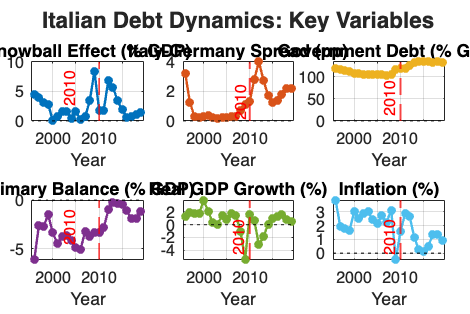


% Figure 1: Time series of key variables
plotTimeSeries(years, data, config.breakYear);

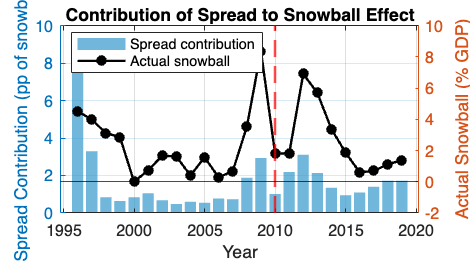


% Figure 2: Spread contribution analysis
plotSpreadContribution(years, data, results2, config.breakYear);

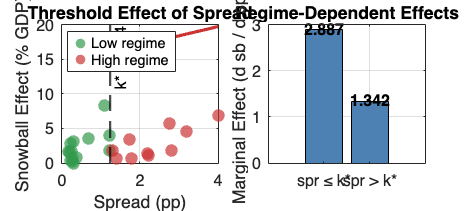


% Figure 3: Threshold visualization
plotThresholdAnalysis(data.spr, data.sb, kstar, results3);

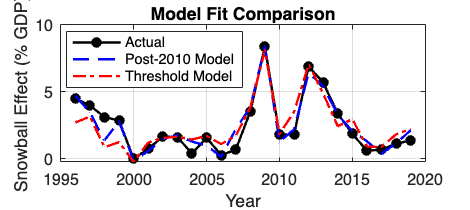


% Figure 4: Model fit comparison
plotModelFit(years, data.sb, X2, results2.beta, X3, results3.beta);


fprintf('All plots generated successfully.\n');

All plots generated successfully.



%% ======================= HELPER FUNCTIONS ==============================

function [data, years] = loadAndPrepareData(config)
    % Load data from Excel and prepare variables for analysis
    
    T = readtable(config.file, 'Sheet', config.sheet, 'VariableNamingRule', 'preserve');
    varNames = T.Properties.VariableNames;
    
    % Identify year columns
    isYear = false(size(varNames));
    for i = 1:numel(varNames)
        y = str2double(varNames{i});
        isYear(i) = ~isnan(y) && y >= config.yearRange(1) && y <= config.yearRange(2);
    end
    yearCols = find(isYear);
    years = str2double(varNames(yearCols))';
    
    % Extract series by code
    sb   = extractSeries(T, config.codes.snowball, yearCols);
    spr  = extractSeries(T, config.codes.spread, yearCols);
    debt = extractSeries(T, config.codes.debt, yearCols);
    rgdp = extractSeries(T, config.codes.realGDP, yearCols);
    pcph = extractSeries(T, config.codes.deflator, yearCols);
    pb   = extractSeries(T, config.codes.primBal, yearCols);
    
    % Compute derived variables
    g   = [NaN; 100 * diff(log(rgdp))];   % Real GDP growth
    pie = [NaN; 100 * diff(log(pcph))];   % Inflation
    b_lag = [NaN; debt(1:end-1)];         % Lagged debt ratio
    D2010 = double(years >= config.breakYear);  % Post-break dummy
    
    % Force column vectors
    sb = sb(:); spr = spr(:); debt = debt(:);
    b_lag = b_lag(:); pb = pb(:); g = g(:); pie = pie(:); D2010 = D2010(:);
    
    % Remove observations with missing values
    Xall = [sb, spr, b_lag, pb, g, pie];
    ok = all(~isnan(Xall), 2);
    
    % Pack into structure
    data.sb    = sb(ok);
    data.spr   = spr(ok);
    data.debt  = debt(ok);
    data.b_lag = b_lag(ok);
    data.pb    = pb(ok);
    data.g     = g(ok);
    data.pie   = pie(ok);
    data.D2010 = D2010(ok);
    
    years = years(ok);
end

function series = extractSeries(T, code, yearCols)
    % Extract a time series by CODE identifier
    
    % Find the CODE column (handle different possible names)
    codeCol = find(strcmpi(T.Properties.VariableNames, 'CODE'), 1);
    if isempty(codeCol)
        codeCol = find(strcmpi(T.Properties.VariableNames, 'code'), 1);
    end
    if isempty(codeCol)
        codeCol = 1;  % Assume first column if not found
    end
    
    % Find row matching the code
    if iscell(T{:, codeCol})
        rowIdx = find(strcmpi(T{:, codeCol}, code), 1);
    else
        rowIdx = find(T{:, codeCol} == code, 1);
    end
    
    if isempty(rowIdx)
        warning('Code "%s" not found in data. Returning NaN.', code);
        series = NaN(numel(yearCols), 1);
        return;
    end
    
    % Extract values
    series = table2array(T(rowIdx, yearCols))';
    series = double(series);
end

function descTable = computeDescriptiveStats(data)
    % Compute descriptive statistics for main variables
    
    vars = [data.sb, data.spr, data.b_lag, data.pb, data.g, data.pie];
    varNames = {'Snowball', 'Spread', 'Debt_GDP', 'PrimBal', 'Growth', 'Inflation'};
    
    stats = zeros(6, size(vars, 2));
    stats(1,:) = mean(vars, 'omitnan');
    stats(2,:) = std(vars, 'omitnan');
    stats(3,:) = min(vars, [], 'omitnan');
    stats(4,:) = max(vars, [], 'omitnan');
    stats(5,:) = median(vars, 'omitnan');
    stats(6,:) = sum(~isnan(vars));
    
    rowNames = {'Mean', 'Std', 'Min', 'Max', 'Median', 'N'};
    descTable = array2table(stats, 'VariableNames', varNames, 'RowNames', rowNames);
end

function results = estimateOLS_HAC(y, X, names, q)
    % OLS estimation with Newey-West HAC standard errors
    %
    % Inputs:
    %   y     - Dependent variable (T×1)
    %   X     - Regressors (T×k, including constant)
    %   names - Variable names (cell array)
    %   q     - HAC bandwidth (number of lags)
    %
    % Output:
    %   results - Structure with estimates and diagnostics
    
    [T, k] = size(X);
    
    % OLS estimation
    beta = X \ y;
    yhat = X * beta;
    resid = y - yhat;
    
    % Degrees of freedom
    df = T - k;
    
    % Variance estimators
    s2 = (resid' * resid) / df;
    XXinv = inv(X' * X);
    
    % OLS standard errors
    V_OLS = s2 * XXinv;
    se_OLS = sqrt(diag(V_OLS));
    
    % HAC (Newey-West) covariance matrix
    u = resid .* X;  % Score contributions
    S = u' * u;      % Lag 0
    
    for j = 1:q
        w = 1 - j/(q + 1);  % Bartlett kernel
        Gamma = u((j+1):end, :)' * u(1:end-j, :);
        S = S + w * (Gamma + Gamma');
    end
    
    V_HAC = XXinv * S * XXinv;
    se_HAC = sqrt(diag(V_HAC));
    
    % Test statistics
    t_OLS = beta ./ se_OLS;
    t_HAC = beta ./ se_HAC;
    p_OLS = 2 * tcdf(-abs(t_OLS), df);
    p_HAC = 2 * tcdf(-abs(t_HAC), df);
    
    % Goodness of fit
    SSR = sum(resid.^2);
    TSS = sum((y - mean(y)).^2);
    R2 = 1 - SSR/TSS;
    adjR2 = 1 - (1 - R2) * (T - 1) / df;
    
    % Information criteria
    AIC = T * log(SSR/T) + 2*k;
    BIC = T * log(SSR/T) + k*log(T);
    
    % Durbin-Watson statistic
    DW = sum(diff(resid).^2) / SSR;
    
    % Pack results
    results.beta = beta;
    results.se_OLS = se_OLS;
    results.se_HAC = se_HAC;
    results.t_OLS = t_OLS;
    results.t_HAC = t_HAC;
    results.p_OLS = p_OLS;
    results.p_HAC = p_HAC;
    results.resid = resid;
    results.yhat = yhat;
    results.R2 = R2;
    results.adjR2 = adjR2;
    results.AIC = AIC;
    results.BIC = BIC;
    results.DW = DW;
    results.nObs = T;
    results.nParams = k;
    results.names = names;
end

function printResults(results, modelName)
    % Print formatted regression results
    
    fprintf('\n--- %s ---\n\n', modelName);
    
    % Create results table
    tbl = table(results.beta, results.se_OLS, results.t_OLS, results.p_OLS, ...
                results.se_HAC, results.t_HAC, results.p_HAC, ...
                'VariableNames', {'Coef', 'SE_OLS', 't_OLS', 'p_OLS', 'SE_HAC', 't_HAC', 'p_HAC'}, ...
                'RowNames', results.names);
    disp(tbl);
    
    % Diagnostics
    fprintf('\nDiagnostics:\n');
    fprintf('  R²     = %.4f\n', results.R2);
    fprintf('  Adj R² = %.4f\n', results.adjR2);
    fprintf('  AIC    = %.2f\n', results.AIC);
    fprintf('  BIC    = %.2f\n', results.BIC);
    fprintf('  DW     = %.3f\n', results.DW);
    fprintf('  N      = %d\n', results.nObs);
end

function exportResults(results, filename)
    % Export results to Excel
    
    if isempty(filename)
        return;
    end
    
    tbl = table(results.beta, results.se_OLS, results.t_OLS, results.p_OLS, ...
                results.se_HAC, results.t_HAC, results.p_HAC, ...
                'VariableNames', {'Estimate', 'SE_OLS', 't_OLS', 'p_OLS', 'SE_HAC', 't_HAC', 'p_HAC'}, ...
                'RowNames', results.names);
    
    writetable(tbl, filename, 'WriteRowNames', true);
    fprintf('Results exported to: %s\n', filename);
end

function kstar = findOptimalThreshold(sb, spr, b_lag, pb, g, pie)
    % Grid search for optimal threshold on spread
    
    k_grid = linspace(prctile(spr, 10), prctile(spr, 90), 50);
    RSS = zeros(numel(k_grid), 1);
    n = numel(sb);
    
    for i = 1:numel(k_grid)
        spr_hi = spr .* (spr > k_grid(i));
        X = [ones(n,1), spr, spr_hi, b_lag, pb, g, pie];
        beta = X \ sb;
        RSS(i) = sum((sb - X*beta).^2);
    end
    
    [~, idx] = min(RSS);
    kstar = k_grid(idx);
end

function compTable = compareModels(models, names)
    % Compare models using information criteria
    
    nModels = numel(models);
    stats = zeros(nModels, 5);
    
    for i = 1:nModels
        stats(i, 1) = models{i}.R2;
        stats(i, 2) = models{i}.adjR2;
        stats(i, 3) = models{i}.AIC;
        stats(i, 4) = models{i}.BIC;
        stats(i, 5) = models{i}.nParams;
    end
    
    compTable = array2table(stats, ...
        'VariableNames', {'R2', 'AdjR2', 'AIC', 'BIC', 'nParams'}, ...
        'RowNames', names);
end

function plotTimeSeries(years, data, breakYear)
    % Plot time series of key macroeconomic variables
    
    figure('Name', 'Macroeconomic Variables', 'Position', [100 100 1200 800], 'Color', 'w');
    tiledlayout(2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    vars = {data.sb, data.spr, data.debt, data.pb, data.g, data.pie};
    titles = {'Snowball Effect (% GDP)', 'Italy-Germany Spread (pp)', ...
              'Government Debt (% GDP)', 'Primary Balance (% GDP)', ...
              'Real GDP Growth (%)', 'Inflation (%)'};
    
    colors = lines(6);
    
    for i = 1:6
        nexttile;
        plot(years, vars{i}, '-o', 'LineWidth', 1.5, 'Color', colors(i,:), ...
             'MarkerSize', 4, 'MarkerFaceColor', colors(i,:));
        hold on;
        xline(breakYear, '--r', sprintf('%d', breakYear), 'LineWidth', 1.2, ...
              'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'left');
        yline(0, 'k:', 'LineWidth', 0.8);
        grid on; box on;
        title(titles{i}, 'FontSize', 11);
        xlabel('Year');
        xlim([min(years)-0.5, max(years)+0.5]);
    end
    
    sgtitle('Italian Debt Dynamics: Key Variables', 'FontSize', 14, 'FontWeight', 'bold');
end

function plotSpreadContribution(years, data, results, breakYear)
    % Plot contribution of spread to snowball effect
    
    figure('Name', 'Spread Contribution', 'Position', [150 150 900 500], 'Color', 'w');
    
    % Extract coefficients
    b_spr = results.beta(2);       % spread
    b_int = results.beta(3);       % spread×D2010
    
    % Compute contributions
    spr_post = data.spr .* data.D2010;
    contrib = b_spr * data.spr + b_int * spr_post;
    
    % Plot
    yyaxis left;
    h1 = bar(years, contrib, 'FaceColor', [0.2 0.6 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.7);
    ylabel('Spread Contribution (pp of snowball)');
    
    yyaxis right;
    h2 = plot(years, data.sb, '-ok', 'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerFaceColor', 'k');
    ylabel('Actual Snowball (% GDP)');
    
    hold on;
    xline(breakYear, '--r', 'LineWidth', 1.5);
    yline(0, 'k-', 'LineWidth', 0.5);
    
    legend([h1, h2], {'Spread contribution', 'Actual snowball'}, 'Location', 'northwest');
    title('Contribution of Spread to Snowball Effect');
    xlabel('Year');
    grid on; box on;
end

function plotThresholdAnalysis(spr, sb, kstar, results)
    % Visualize threshold regression results
    
    figure('Name', 'Threshold Analysis', 'Position', [200 200 1000 450], 'Color', 'w');
    
    % Left panel: Scatter with regime coloring
    subplot(1, 2, 1);
    lowIdx = spr <= kstar;
    highIdx = spr > kstar;
    
    scatter(spr(lowIdx), sb(lowIdx), 60, [0.2 0.6 0.3], 'filled', 'MarkerFaceAlpha', 0.7);
    hold on;
    scatter(spr(highIdx), sb(highIdx), 60, [0.8 0.2 0.2], 'filled', 'MarkerFaceAlpha', 0.7);
    
    % Fitted lines by regime
    sprRange_low = linspace(min(spr), kstar, 50);
    sprRange_high = linspace(kstar, max(spr), 50);
    
    b1 = results.beta(2);
    b2 = results.beta(3);
    const = results.beta(1);
    
    % Simplified predictions (holding other vars at mean)
    yhat_low = const + b1 * sprRange_low;
    yhat_high = const + b1 * sprRange_high + b2 * (sprRange_high - 0);
    
    plot(sprRange_low, yhat_low, '-', 'Color', [0.2 0.6 0.3], 'LineWidth', 2);
    plot(sprRange_high, yhat_high, '-', 'Color', [0.8 0.2 0.2], 'LineWidth', 2);
    
    xline(kstar, '--k', sprintf('k* = %.2f', kstar), 'LineWidth', 1.5, ...
          'LabelVerticalAlignment', 'top');
    
    xlabel('Spread (pp)');
    ylabel('Snowball Effect (% GDP)');
    title('Threshold Effect of Spread');
    legend({'Low regime', 'High regime'}, 'Location', 'northwest');
    grid on; box on;
    
    % Right panel: Marginal effects
    subplot(1, 2, 2);
    effects = [b1, b1 + b2];
    bar(effects, 'FaceColor', [0.3 0.5 0.7]);
    set(gca, 'XTickLabel', {'spr ≤ k*', 'spr > k*'});
    ylabel('Marginal Effect (d sb / d spr)');
    title('Regime-Dependent Effects');
    grid on; box on;
    
    % Add value labels
    for i = 1:2
        text(i, effects(i) + 0.02*sign(effects(i)), sprintf('%.3f', effects(i)), ...
             'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
end

function plotModelFit(years, sb, X2, beta2, X3, beta3)
    % Compare model fit across specifications
    
    figure('Name', 'Model Fit', 'Position', [250 250 900 400], 'Color', 'w');
    
    yhat2 = X2 * beta2;
    yhat3 = X3 * beta3;
    
    plot(years, sb, '-ok', 'LineWidth', 1.5, 'MarkerFaceColor', 'k', 'MarkerSize', 5);
    hold on;
    plot(years, yhat2, '--b', 'LineWidth', 1.5);
    plot(years, yhat3, '-.r', 'LineWidth', 1.5);
    
    legend({'Actual', 'Post-2010 Model', 'Threshold Model'}, 'Location', 'best');
    xlabel('Year');
    ylabel('Snowball Effect (% GDP)');
    title('Model Fit Comparison');
    grid on; box on;
end